A = importdata('./data_problem3(2)/A1.txt');
b = importdata('./data_problem3(2)/b1.txt');
x1 = importdata('./data_problem3(2)/x1.txt');

clf;
n=10;
x = zeros([n,1]);
epi = 100;
error_Jacobi = [];
% Jacobi
while epi >= 1e-4
    y = x;
    for j = 1:n
        y(j) = (b(j) - A(j,:) * x + A(j,j) * x(j))/ A(j,j);
    end
    epi = norm(y-x,2);
    x = y;
end
x;
%error
x = zeros([n,1]);
for k = 1:50
    y = x;
    for j = 1:n
        y(j) = (b(j) - A(j,:) * x + A(j,j) * x(j))/ A(j,j);
    end
    x = y;
    error_Jacobi = [error_Jacobi, norm(x1-x,2)];
end
x;

%Gauss-Seidel
x = zeros([n,1]);
epi = 100;
error_GS = [];
while epi >= 1e-4
    y = x;
    for j = 1:n
        x(j) = (b(j) - A(j,:) * x + A(j,j) * x(j))/ A(j,j);
    end
    epi = norm(y-x, 2);
end
x;
%error
x = zeros([n,1]);
for k = 1:50
    y = x;
    for j = 1:n
        x(j) = (b(j) - A(j,:) * x + A(j,j) * x(j))/ A(j,j);
    end
    error_GS = [error_GS, norm(x1-x,2)];
end
x;


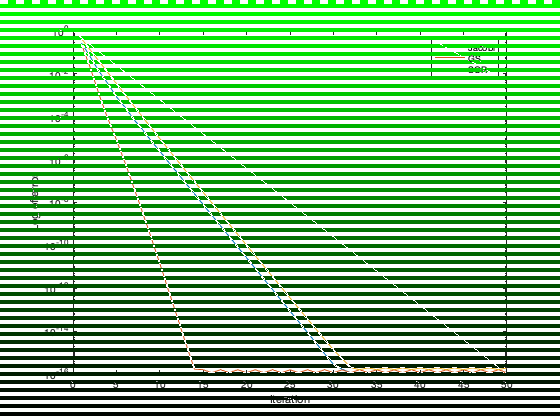

%error
x = zeros([n,1]);
error_SOR = [];
w = 0.8;
for k = 1:50
    y = x;
    for j = 1:n
        x(j) = (1-w)*y(j) + w*(b(j)-A(j,:) * x + A(j,j) * x(j))/A(j,j);
    end
    error_SOR = [error_SOR, norm(x1-x,2)];
end
semilogy(error_Jacobi);
hold on;
semilogy(error_GS);
hold on;
semilogy(error_SOR);
xlabel('Iteration');ylabel('Log of error');legend('Jacobi','GS','SOR');

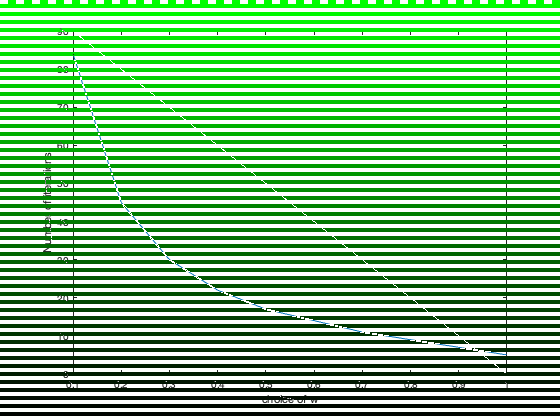

clf;
% SOR

counts = [];
for w =0.1:0.1:1
    x = zeros([n,1]);
    count = 0;
    epi = 100;
    while epi >= 1e-4
        y = x;
        for j = 1:n
            x(j) = (1-w)*y(j) + w*(b(j)-A(j,:) * x + A(j,j) * x(j))/A(j,j);
        end
        epi = norm(y-x, 2);
        count = count + 1;
    end
    counts = [counts, count];
end
plot(0.1:0.1:1,counts);xlabel('choice of w');ylabel('Number of iterations');

A = importdata('./data_problem3(2)/A2.txt');
b = importdata('./data_problem3(2)/b2.txt');
x1 = importdata('./data_problem3(2)/x2.txt');
n=1000;
x = zeros([n,1]);
epi = 100;
% Jacobi
error_Jacobi = [];
while epi >= 0.0001
    y = x;
    for j = 1:n
        y(j) = (b(j) - A(j,:) * x + A(j,j) * x(j))/ A(j,j);
    end
    epi = norm(y-x,2);
    x = y;
end
x;
%error
x = zeros([n,1]);
for k = 1:50
    y = x;
    for j = 1:n
        y(j) = (b(j) - A(j,:) * x + A(j,j) * x(j))/ A(j,j);
    end
    x = y;
    error_Jacobi = [error_Jacobi, norm(x1-x,2)];
end
x;
%Gauss-Seidel
x = zeros([n,1]);
epi = 100;
while epi >= 0.0001
    y = x;
    for j = 1:n
        x(j) = (b(j) - A(j,:) * x + A(j,j) * x(j))/ A(j,j);
    end
    epi = norm(y-x,2);
end
x;
%error
error_GS = [];
x = zeros([n,1]);
for k = 1:50
    y = x;
    for j = 1:n
        x(j) = (b(j) - A(j,:) * x + A(j,j) * x(j))/ A(j,j);
    end
    error_GS = [error_GS, norm(x1-x,2)];
end
x;

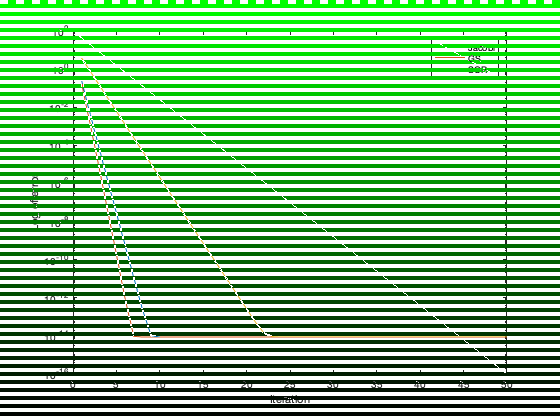

%error
x = zeros([n,1]);
error_SOR = [];
w = 0.8;
for k = 1:50
    y = x;
    for j = 1:n
        x(j) = (1-w)*y(j) + w*(b(j)-A(j,:) * x + A(j,j) * x(j))/A(j,j);
    end
    error_SOR = [error_SOR, norm(x1-x,2)];
end
semilogy(error_Jacobi);
hold on;
semilogy(error_GS);
hold on;
semilogy(error_SOR);
xlabel('Iteration');ylabel('Log of error');legend('Jacobi','GS','SOR');

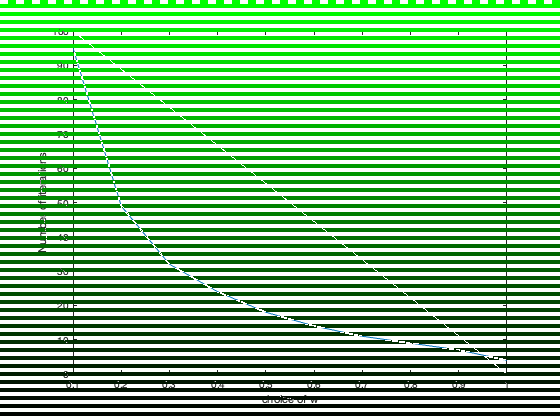

clf;
% SOR
counts = [];
for w =0.1:0.1:1
    x = zeros([n,1]);
    count = 0;
    epi = 100;
    while epi >= 0.0001
        y = x;
        for j = 1:n
            x(j) = (1-w)*y(j) + w*(b(j)-A(j,:) * x + A(j,j) * x(j))/A(j,j);
        end
        epi = norm(y-x, 2);
        count = count + 1;
    end
    counts = [counts, count];
end
plot(0.1:0.1:1,counts);xlabel('choice of w');ylabel('Number of iterations');